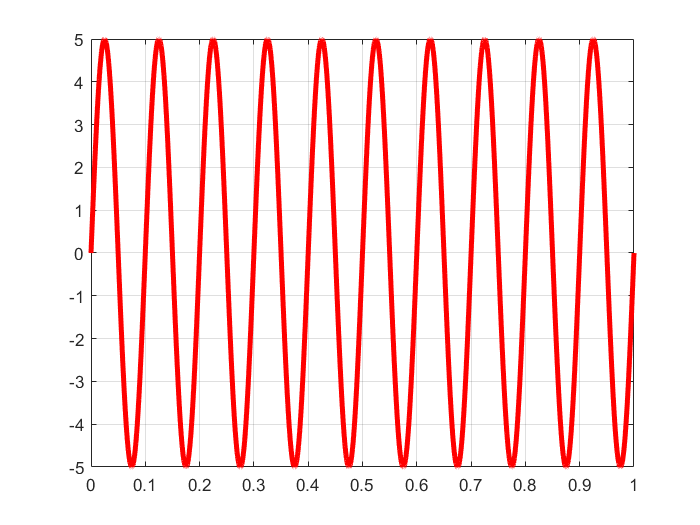

t=0:0.0005:1;    %区间0到1
f=5*sin(2*pi*10*t);  %幅值5，频率10hz
plot(t,f,'r','LineWidth',3);
grid on;       %打开图形窗口中的坐标轴网格显示

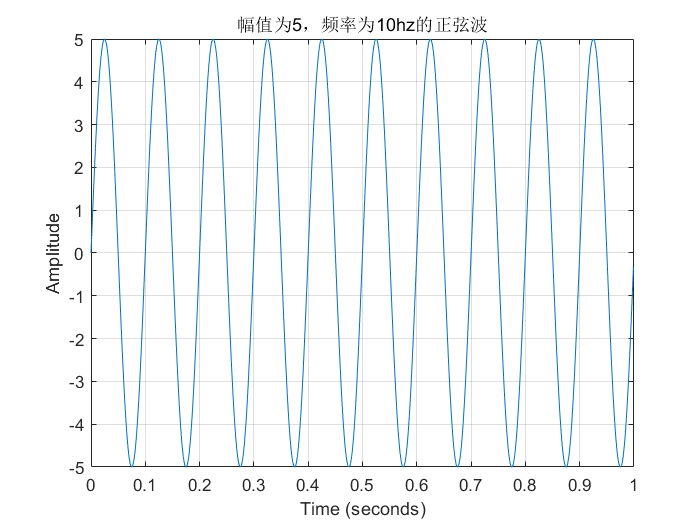

% 参数设置
fs = 1000;           % 采样频率
duration = 1;        % 持续时间，此处设为1秒
amplitude = 5;       % 正弦波的幅值
frequency = 10;      % 正弦波的频率

% 时间向量
timeVector = 0:1/fs:duration-1/fs;

% 生成正弦信号
signal = amplitude * sin(2*pi*frequency*timeVector);

% 绘图显示信号
plot(timeVector, signal);
xlabel('Time (seconds)');
ylabel('Amplitude');
title('幅值为5，频率为10hz的正弦波');
grid on;

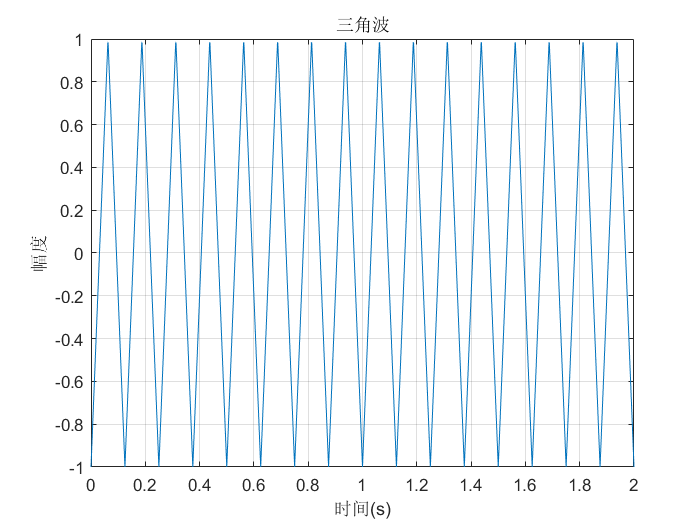

% 参数设置
Fs = 1000;      % 采样频率
t = 0:1/Fs:2;   % 时间向量
x = sawtooth(2*pi*8*t, 0.5); % 生成三角波，50Hz，第二个参数0.5表示波形对称，即三角波

% 绘制三角波
plot(t, x);
title('三角波');
xlabel('时间(s)');
ylabel('幅度');
grid on;

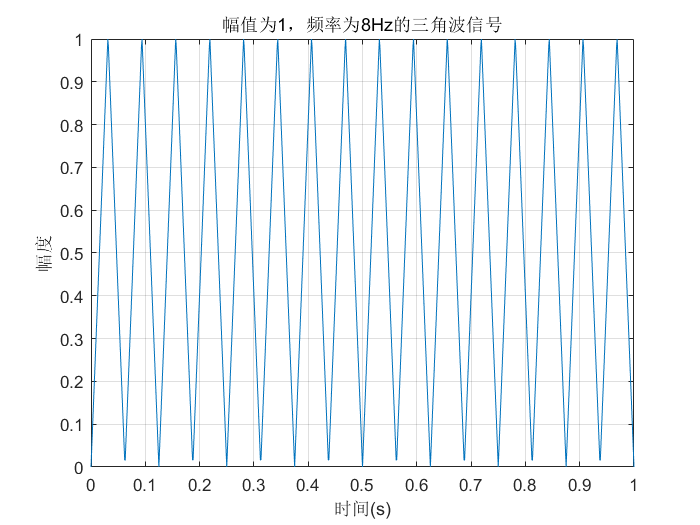

% 设置参数
fs = 1000;       % 采样频率
duration = 1;    % 信号持续时间，设为1秒
amp = 1;         % 幅值
freq = 8;        % 波形频率

% 创建时间向量
t = 0:1/fs:duration;

% 使用sawtooth函数生成波形
% 注意，通过将相位偏移设置为90度，以及后续处理，使锯齿波变为三角波
triWave = sawtooth(2*pi*freq*t, 0.5);

% 将sawtooth函数的输出调整为三角波形状
% 这里我们取绝对值后，再对其反向映射，从而形成三角波
triWave = abs(triWave);
triWave = 2 * (0.5 - triWave) + 1;

% 缩放幅值
triWave = triWave * (amp / max(triWave));

% 绘制信号图像
plot(t, triWave);
xlabel('时间(s)');
ylabel('幅度');
title('幅值为1，频率为8Hz的三角波信号');
grid on;

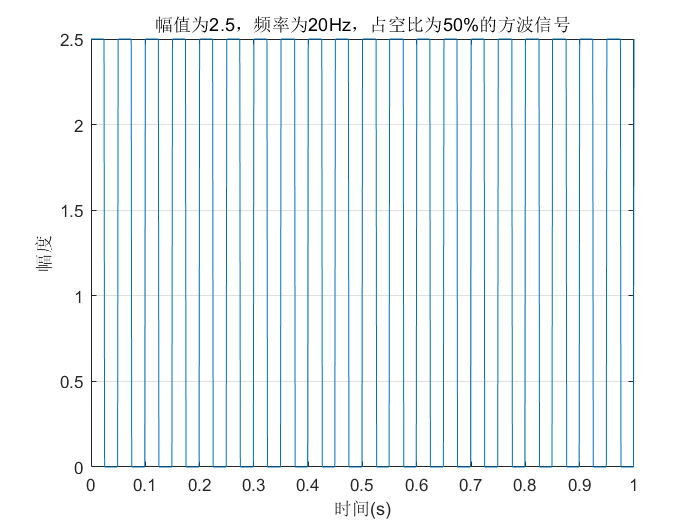

% 设置参数
fs = 1000;         % 采样频率
duration = 1;      % 信号持续时间，设为1秒
amp = 2.5;         % 幅值
freq = 20;         % 方波频率
duty = 50;         % 占空比

% 创建时间向量
t = 0:1/fs:duration;

% 生成方波信号
% square函数的第二个参数表示占空比，单位是百分比
wave = amp * (square(2*pi*freq*t, duty) + 1) / 2;

% 绘制信号图像
plot(t, wave);
xlabel('时间(s)');
ylabel('幅度');
title('幅值为2.5，频率为20Hz，占空比为50%的方波信号');
grid on;

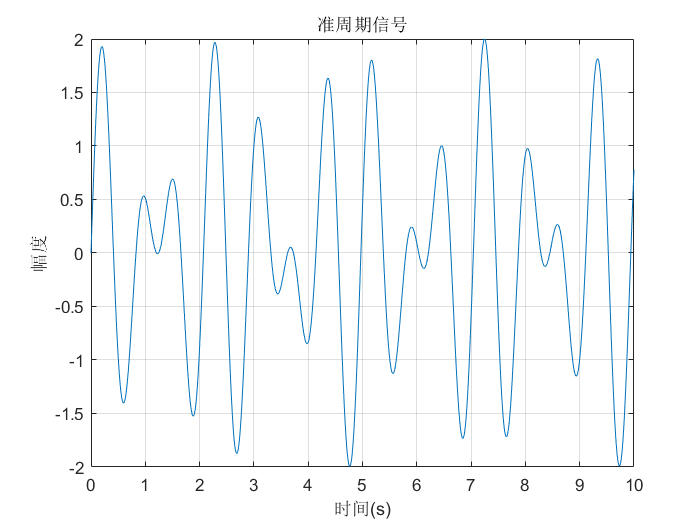

% 设置参数
fs = 100;          % 采样频率
t = 0:1/fs:10;     % 时间向量，从0到10秒
freq1 = 1;         % 第一个正弦波频率
freq2 = sqrt(2);  % 第二个正弦波频率

% 生成两个正弦波
wave1 = sin(2*pi*freq1*t);
wave2 = sin(2*pi*freq2*t);

% 构成准周期信号
quasiPeriodicSignal = wave1 + wave2;

% 绘制信号
plot(t, quasiPeriodicSignal);
xlabel('时间(s)');
ylabel('幅度');
title('准周期信号');
grid on;

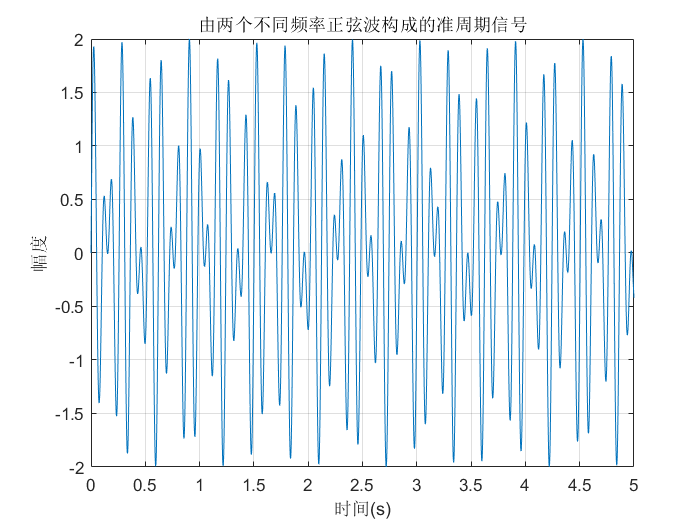

% 设置参数
fs = 1000;       % 采样频率
duration = 5;   % 信号持续时间，设为5秒

% 创建时间向量
t = 0:1/fs:duration;

% 定义两个正弦信号的频率
freq1 = 8;       % 第一个正弦波频率
freq2 = sqrt(2)*8; % 第二个正弦波频率，与第一个频率成无理数比，以实现准周期性

% 生成两个正弦信号
sine1 = sin(2*pi*freq1*t);
sine2 = sin(2*pi*freq2*t);

% 生成准周期信号，这里简单地将两个正弦信号相加
quasiPeriodicSignal = sine1 + sine2;

% 绘制信号图像
plot(t, quasiPeriodicSignal);
xlabel('时间(s)');
ylabel('幅度');
title('由两个不同频率正弦波构成的准周期信号');
grid on;

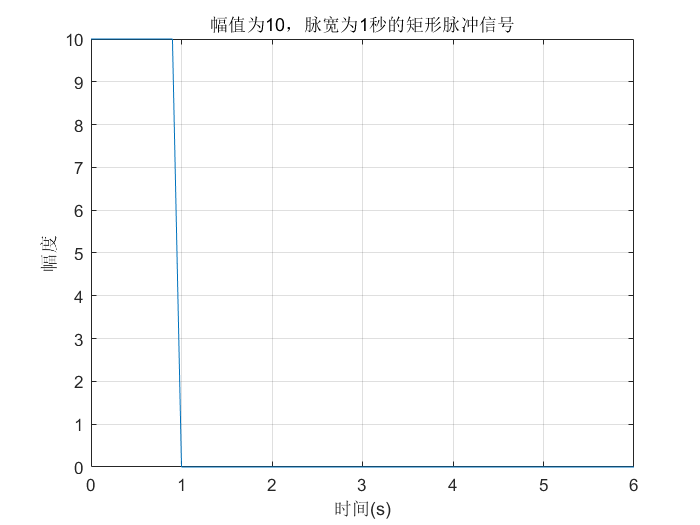

% 设置参数
fs = 10;         % 采样频率
t = 0:1/fs:6;      % 时间向量，从0到6秒
amp = 10;          % 幅值
pulseWidth = 1;    % 脉冲宽度（秒）

% 生成矩形脉冲信号
rectPulse = (t >= 0 & t < pulseWidth) * amp;

% 绘制信号
plot(t, rectPulse);
xlabel('时间(s)');
ylabel('幅度');
title('幅值为10，脉宽为1秒的矩形脉冲信号');
grid on;

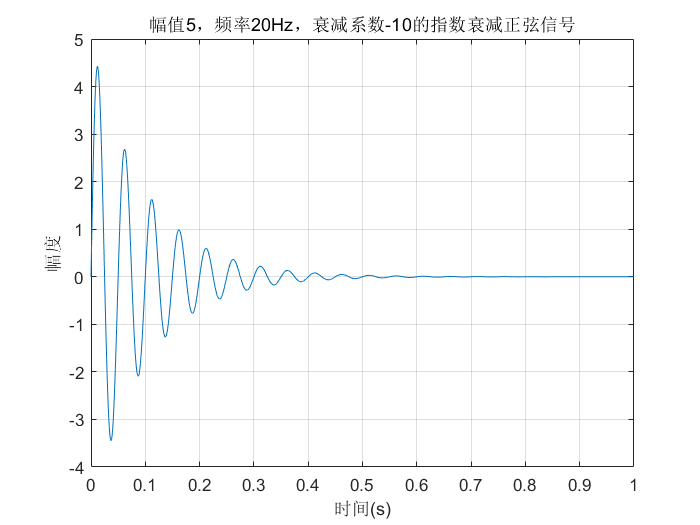

% 定义参数
fs = 1000;             % 设定采样频率为1kHz
duration = 1;          % 信号总持续时间，设为1秒
amp = 5;               % 幅值
freq = 20;             % 正弦波频率，单位Hz
decayRate = -10;       % 衰减率

% 创建时间向量
t = 0:1/fs:duration;

% 生成衰减正弦信号
y = amp .* exp(decayRate*t) .* sin(2*pi*freq*t);

% 绘制信号图像
plot(t, y);
xlabel('时间(s)');
ylabel('幅度');
title('幅值5，频率20Hz，衰减系数-10的指数衰减正弦信号');
grid on;

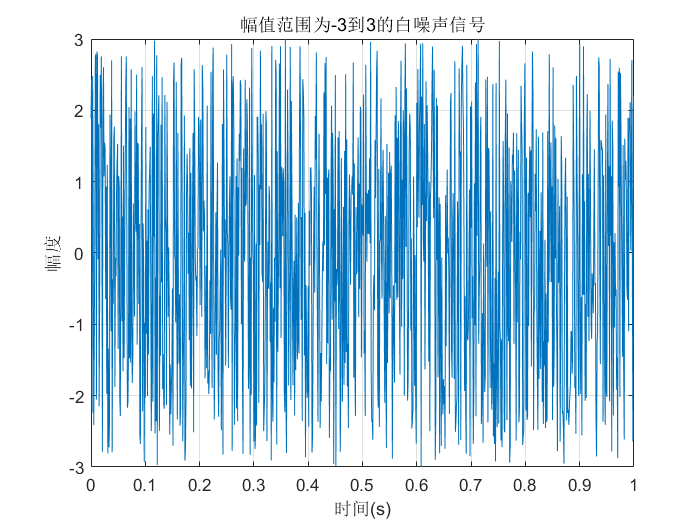

% 设置参数
fs = 1000;          % 采样频率
duration = 1;       % 信号持续时间，设为1秒
ampRange = [-3, 3]; % 幅值范围

% 创建时间向量
t = 0:1/fs:duration-1/fs;

% 生成白噪声信号
% 使用rand函数生成[0,1)之间的均匀分布，然后缩放到[-3,3]范围
noiseSignal = (ampRange(2) - ampRange(1)) * rand(size(t)) + ampRange(1);

% 绘制信号图像
plot(t, noiseSignal);
xlabel('时间(s)');
ylabel('幅度');
title('幅值范围为-3到3的白噪声信号');
grid on;